f_eval=figure();
f_abs=figure();

figure(f_eval);
Area=zeros([8,8]);Area_org=zeros([8,8]);
for i=1:1:8
    for j=1:1:8
        Area_org(i,j)=H2_eval(freq,abs(FRF_org(i,j,:)));
       Area(i,j)=H2_eval(freq,abs(FRF(i,j,:)));
    end
end
evaluated=diag(Area./Area_org)

evaluated =     0.6393
    0.6930
    0.6392
    0.6045
    0.6155
    0.5751
    0.6507
    0.5692


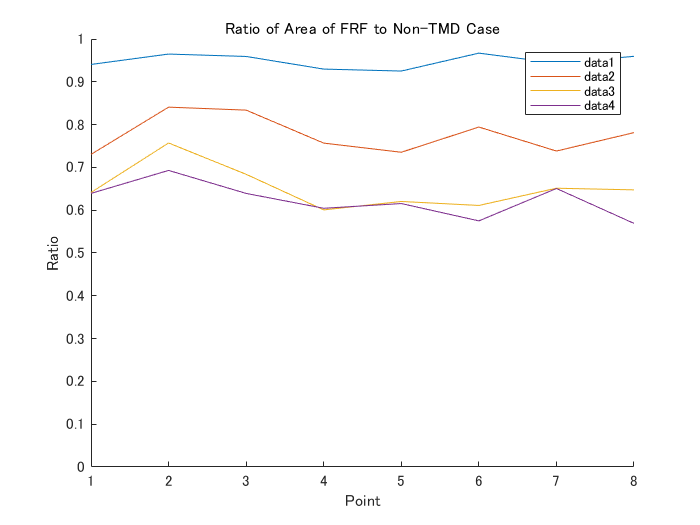

hold on

plot(evaluated)
ylim([0,1])
title("Ratio of Area of FRF to Non-TMD Case")
legend()
xlabel("Point")
ylabel("Ratio")

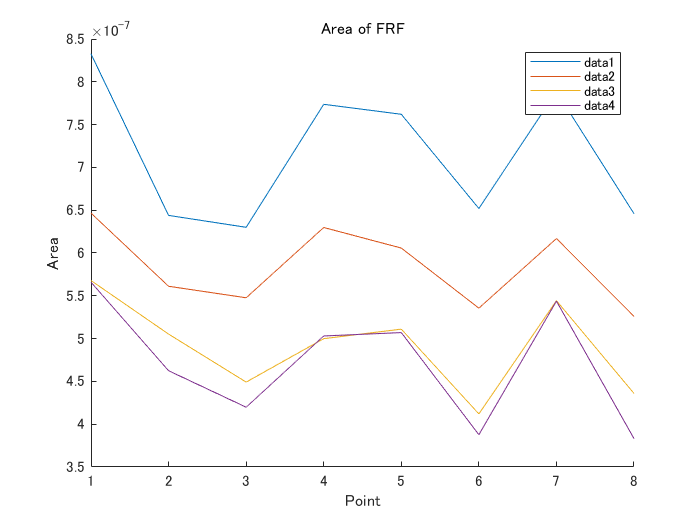

figure(f_abs);
hold on
plot(diag(Area))
title("Area of FRF")
legend()
xlabel("Point")
ylabel("Area")